% Audio Input Settings
deviceNum = 0;
sampleRate = 48000; % Hz
bitsPerSample = 16;
numAudioChannels = 1; 
recordTime = 5; % record time in seconds

info = audiodevinfo;
inputDevices = struct2table(info.input)

inputDevices = 2×3 table
                                   Name                                       DriverVersion        ID
    __________________________________________________________________    _____________________    __

    'Primary Sound Capture Driver (Windows DirectSound)'                  'Windows DirectSound'    0 
    'Microphone (Realtek High Definition Audio) (Windows DirectSound)'    'Windows DirectSound'    1 


recorder = audiorecorder(sampleRate,bitsPerSample,numAudioChannels,deviceNum);

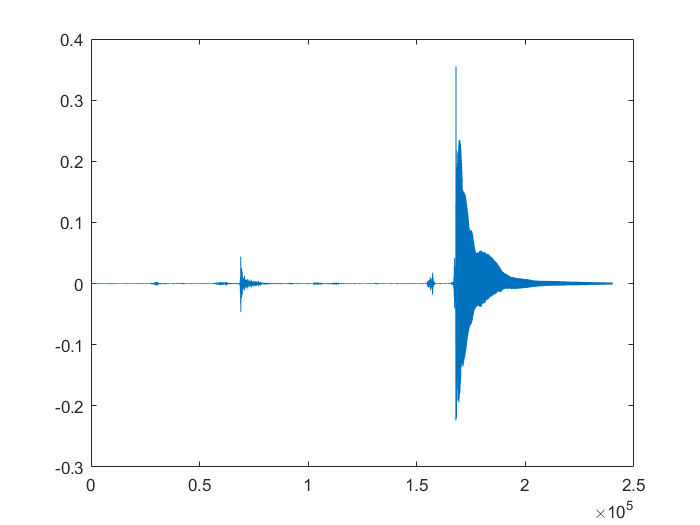

recordblocking(recorder, 5);
play(recorder);
y = getaudiodata(recorder);
plot(y);